`In the name of God`

# Blind Source Separation

## HW #2

**Maryam Riazi**

**810197518**

### Question1.

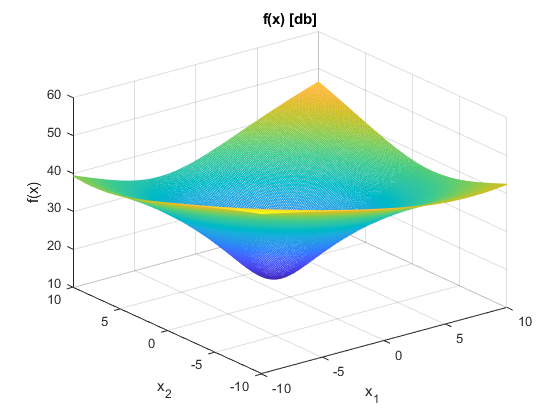

[x1,x2] = meshgrid(-10:0.1:10);
f = x1.*x1 + x2.*x2- 4*x1 -6*x2 + 13 + x1.*x2;
fdb =  20*log10(f);
figure
mesh(x1,x2,fdb)
title('f(x) [db]')
xlabel('x_1')
ylabel('x_2')
zlabel('f(x)')

### Question2.

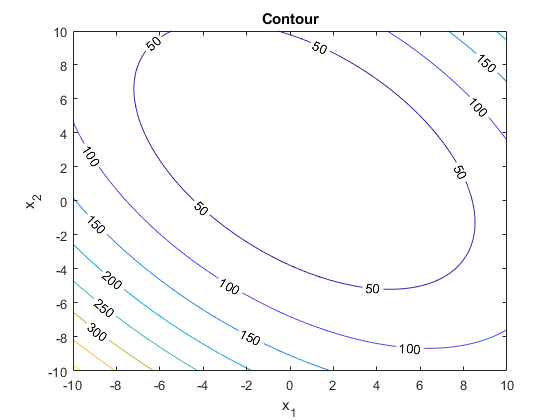

figure
contour(x1,x2,f,'ShowText','on')
title('Contours of f(x)')
xlabel('x_1')
ylabel('x_2')

### Question3.

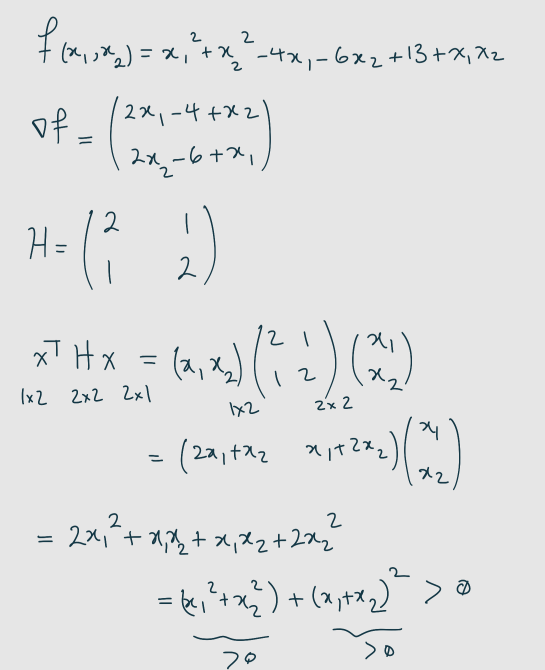

### Question4.

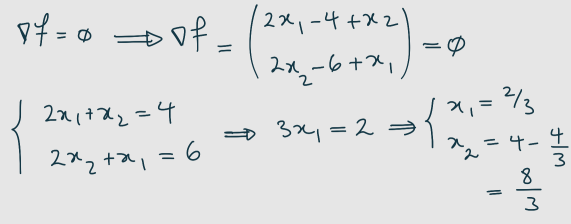

### Question5.

Steepest decent Algorithm is as below (my "SD" function act exactly as below):


$$\left\lbrack \begin{array}{c}
x_1^{\left(k+1\right)} \\
x_2^{\left(k+1\right)} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_1^{\left(k\right)} \\
x_2^{\left(k\right)} 
\end{array}\right\rbrack -\mu \nabla_{x^{\left(k\right)} } f$$


X = [6;6];
mio1 = 0.01;
mio2 = 0.1;
[OptimalX1,fvalues1,iterations1]=SD(X,mio1)

OptimalX1 =     0.6667
    2.6666


fvalues1 =    57.6508   54.4988   51.5322   48.7403   46.1126   43.6395   41.3119   39.1211   37.0591   35.1183   33.2916   31.5722   29.9538   28.4304   26.9964   25.6466   24.3760   23.1800   22.0540   20.9941   19.9963   19.0569   18.1725   17.3399   16.5560   15.8180   15.1231   14.4688   13.8527   13.2726   12.7263   12.2119   11.7275   11.2713   10.8417   10.4370   10.0559    9.6969    9.3588    9.0403    8.7403    8.4576    8.1913    7.9404    7.7040    7.4813    7.2714    7.0736    6.8872    6.7115


iterations1 = 951

[OptimalX2,fvalues2,iterations2]=SD(X,mio2)

OptimalX2 =     0.6667
    2.6666


fvalues2 =    32.0800   17.8484   10.8257    7.3446    5.6066    4.7288    4.2775    4.0392    3.9085    3.8332    3.7872    3.7572    3.7366    3.7216    3.7103    3.7016    3.6948    3.6893    3.6850    3.6815    3.6787    3.6764    3.6745    3.6730    3.6718    3.6708    3.6700    3.6694    3.6689    3.6685    3.6681    3.6678    3.6676    3.6674    3.6673    3.6672    3.6671    3.6670    3.6669    3.6669    3.6668    3.6668    3.6668    3.6668    3.6667    3.6667    3.6667    3.6667    3.6667    3.6667


iterations2 = 91

#### A) 

Yes! In both cases the function converges but in different paces.

#### B) 

As it is shown in above results for $\mu$ = 0.01, 951 iterations are needed but for $\mu$ = 0.1, only 91 iterartions are needed. 

#### C)

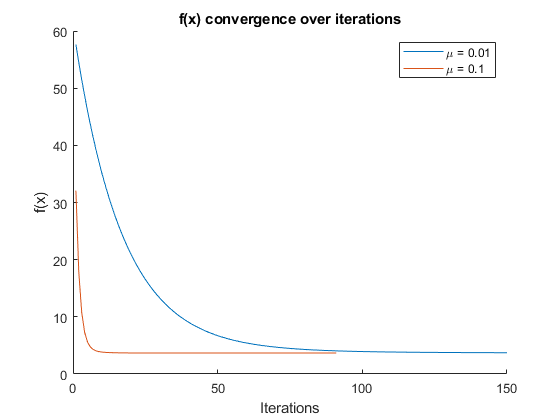

figure
hold on
plot (1:150,fvalues1(1:150));
plot (1:iterations2,fvalues2);
title('f(x) convergence over iterations')
xlabel('Iterations')
ylabel('f(x)')
legend('\mu = 0.01','\mu = 0.1','Location','northeast')
hold off

### Question6.

#### A)

Newton Algorithm is as below (my "Newton" function is exactly as below):


$$\left\lbrack \begin{array}{c}
x_1^{\left(k+1\right)} \\
x_2^{\left(k+1\right)} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_1^{\left(k\right)} \\
x_2^{\left(k\right)} 
\end{array}\right\rbrack -{H_{x^{\left(k\right)} }^{-1} \nabla }_{x^{\left(k\right)} } f$$


[OptimalNewtonX,fvaluesNewton,iterationsNewton] = Newton(X)

OptimalNewtonX =     0.6667
    2.6667


fvaluesNewton = 3.6667

iterationsNewton = 1

#### B)

At each iteration, Newton's method attempts to fit a paraboloid on f(x) at $x^{\left(k\right)}$, find the minimum of the paraboloid and then find the projection of that point on f(x). This process will be done exactly over and over again.

In our case, f is a quadratic function, so the exact extremum is found in one step!

### Question7.

In Alternation Minimization algorithm all we do is exactly as in S.D algorithm with a little difference!

The difference is as that in this algorithm we do gradient descent one time assuming x1 is fixed and the other time x2 is fixed.

This process should be iterated as much as the function converges! 


$$x_1^{\left(1\right)} =x_2^{\left(1\right)} =6$$


(2) $x_2^{\left(2\right)}$: $\nabla f\left(x_1 \right)=2x_1 -4+x_2 =0\Rightarrow x_1^{\left(2\right)} =\frac{4-x_2 }{2}=-1$

(3) $x_1^{\left(3\right)} =-1$: $\nabla f\left(x_2 \right)=2x_2 -6+x_1 =0\Rightarrow x_2^{\left(3\right)} =\frac{6-x_1 }{2}=\frac{7}{2}$

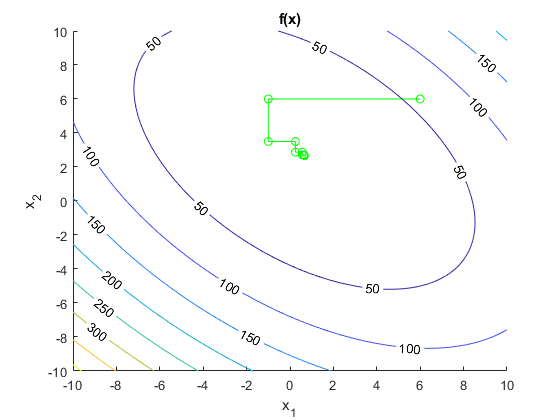

[OptimalAMX_1,OptimalAMX_2]=AM(X);
figure
hold on
plot(OptimalAMX_1,OptimalAMX_2,'-o','Color','green')
contour(x1,x2,f,'ShowText','on')
xlim([-10 10])
ylim([-10 10])
title('f(x)')
xlabel('x_1')
ylabel('x_2')
hold off

### Question8.


$$f\left(x\right)=x_1^2 +x_2^2 -4x_1 -6x_2 +13+x_1 x_2$$


s.t $\left\lbrace \begin{array}{cc}
-10<x_1 ,x_2 <10 & \;\\
 & \;\\
x_1^2 +x_2^2 =1 & \;
\end{array}\right.$

For any point $P=\left(x_1 ,x_2 \right)$ in 2D plane, the projection of it on the unit circle would be:

 
$$\theta ={\textrm{tg}}^{-1} \left(\frac{x_2 }{x_1 }\right)$$



$$P^{\prime } =\left(\cos \left(\theta \right),\sin \left(\theta \right)\right)$$


X = [6;6];
mio = 0.1;
[OptimalX,min_fvalue] = Gradient_projection(X,mio)

X =     0.4943
    0.8693


min_fvalue = 7.2367

### Question9.

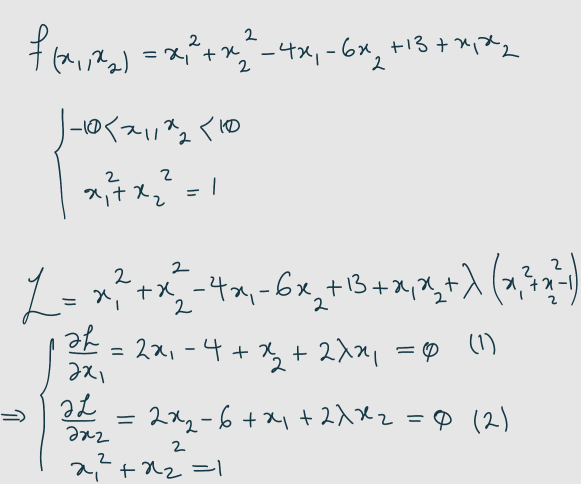

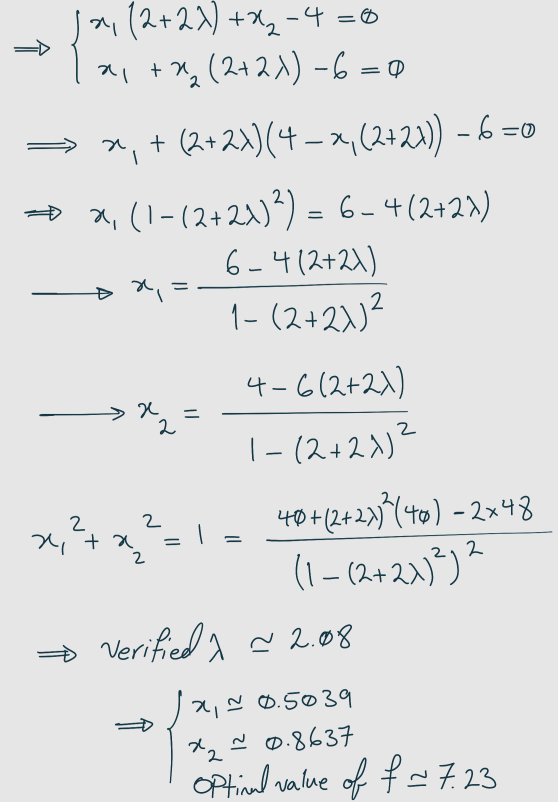

As we could see the Lagrangian method proved the Gradient Projection method.

### Functions

function [OptimalX,fvalues,iterations] = SD(X,mio)
fvalues = [];
gradf = [2*X(1)-4+X(2);2*X(2)-6+X(1)];
norm(gradf);
iterations = 0;
while (norm(gradf)>0.0001)
    X = X - mio*gradf;
    iterations = iterations + 1;
    fvalues(iterations) = X(1)^2+X(2)^2-4*X(1)-6*X(2)+13+X(1)*X(2);
    gradf = [2*X(1)-4+X(2);2*X(2)-6+X(1)];
end
OptimalX = X;
end
%%%%%%%%%%%
function [OptimalX,fvalues,iterations] = Newton(X)
fvalues = [];
Hessianf = [2 1
    1 2];
gradf = [2*X(1)-4+X(2);2*X(2)-6+X(1)];
iterations = 0;
while (norm(gradf)>0.0001)
    X = X - inv(Hessianf)*gradf;
    iterations = iterations + 1;
    fvalues(iterations) = X(1)^2+X(2)^2-4*X(1)-6*X(2)+13+X(1)*X(2);
    gradf = [2*X(1)-4+X(2);2*X(2)-6+X(1)];
end
OptimalX = X;
end
%%%%%%%%%%%%
function [Xvalues_1,Xvalues_2] = AM(X)
Xvalues_1=[];
Xvalues_2=[];
iteration = 1;
while true
    Xvalues_1 = [Xvalues_1 X(1)];
    Xvalues_2 = [Xvalues_2 X(2)];
    if (length(Xvalues_1) >= 100)
        break;
    end
    if mod(iteration,2) == 1
        X(1) = (4-X(2))/2;
    else
        X(2) = (6-X(1))/2;
    end
    iteration = iteration + 1;
end
end
%%%%%%%%%%%%
function [OptimalX,fvalues] = Gradient_projection(X,mio)
iterations = 0;
while iterations<100
    fvalues = X(1)^2+X(2)^2-4*X(1)-6*X(2)+13+X(1)*X(2);
    gradf = [2*X(1)-4+X(2)
        2*X(2)-6+X(1)];
    
    X(1) = X(1)-mio*gradf(1);
    X(2) = X(2)-mio*gradf(2);
    
    theta = atan(X(2)/X(1));
    X(1) = cos(theta); %mitooni inja biyay va
    X(2) = sin(theta);
    iterations = iterations + 1;
end
OptimalX = X;
end